# ** PROJET D'OPTIMISATION GLOBALE**

# **PARTIE 1 **

**Objectif :** Minimiser le coût de revient du réseau sur une journée d’été.

La variable d'optimisation X est un vecteur ligne 1x48. Les 24 premières colonnes correspondent aux puissances fournies à l'électrolyseur à chaque heure sur les 24h de la journée. Les 24 colonnes suivantes correspondent aux valeurs teta_elec associée à chaque heure de la journée. teta_elec vaut 1 (on) si on active l'électrolyseur et 0 (off) si on ne l'allume pas. 

clear 

data = load ("EteV35Nu10.txt") ;

N = 24 ; %N = nombre d'heures étudiées (On a 2N variables dans notre vecteur d'étude)

%Données à chaque heure 
H = data(:,1) ; %les 24 heures de la journée 
D = data(:,2)'; %vecteur Nx1 des demandes en électricité par heure sur 24h en MW
Peol = data(:,3)'; %vecteur de la puissance éolienne produite par heure en MW 
Ppv = data(:,4)'; %vecteur de la puissance solaire produite par heure en MW
Cext = data(:,end)' ; %Coût de l'électricité du réseau par heure en €/MW
Celec = ones(1,N) ; %Coût de fonctionnement de l'électrolyseur en €/MW

%Autres données
etat_elec = 0.6 ; %Rendement de l'électrolyseur 
Pmax_elec = 30 ;%Pmax de l'électrolyseur par heure en MW 
Pmin_elec = 5 ; %Pmin de l'électrolyseur par heure  en MW

%Quantités minimales d'hydrogène à produire par jour en MW (choisie arbitrairement)
Qjour_H2_ga = linspace(50,200,4); %pour le solver ga
Qjour_H2_pso = [100]; %pour le solver pso 


### **1.Définition de la fonction objectif à minimiser**

La fonction objectif à minimiser est la fonction des coûts de la production électrique sur une journée d'été en fonction des puissances fournies à l'électrolyseur et des variables "on-off" (définissent si l'électrolyseur fonctionne ou pas) à chaque heure. 

Pext = D + Pelec - Peol - Ppv 

Si Pext > 0 --> on achète de l'électricité au réséau

Si Pext < 0 --> on vend de l'électricité au réséau

Si Pext = 0 --> on ne fait rien 

%fonction objectif (prend un vecteur ligne en entrée pour être compatible
%avec le solver ga) 

%Le premier terme de la somme correspond au coût (positif ou négatif) lié à
%l'achat ou la vente d'ékectricité sur le réseau. Le deuxième terme
%correspond au coût de fonctionnement de l'électrolyseur. 

fobj = @(X) (D +X(1,1:N).*X(1,N+1:2*N) - Peol - Ppv)*Cext' + X(1,1:N).*X(1,N+1:2*N)*Celec' ; 


### **2.Définition des contraintes**

%Contraintes inégalités linéaires 

%Contrainte Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 ≥ 𝑄𝐻2𝑗𝑜𝑢r soit -Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 <= -𝑄𝐻2𝑗𝑜𝑢r
Aineq_lin1 = [-etat_elec*ones(1,N),zeros(1,N)] ;
% bineq_lin1 : défini dans la boucle for en partie 4 

%Contraintes Pelec > teta_elec*Pmin soit -Pelec + teta_elec*Pmin < 0
Aineq_lin2 = [-eye(N,N),Pmin_elec*eye(N,N)] ;
bineq_lin2 = zeros(N,1) ; 

% Contraintes Pelec <= teta_elec*Pmax soit Pelec- teta_elec*Pmax <= 0
Aineq_lin3 = [eye(N,N),-Pmax_elec*eye(N,N)] ;
bineq_lin3 = zeros(N,1) ; 

%Contrainte inégalité 0 <= teta <= 1  comprise dans les bornes

%Matrices globales contenant toutes les contraintes inégalités linéaires 
Aineq_lin = [Aineq_lin1 ; Aineq_lin2 ; Aineq_lin3 ] ; 
% bineq_lin : défini dans la boucle for en partie 4 

%Contrainte égalité linéaire comprise dans la fonction objectif 
%Pext = D + Pelec - Peol - Ppv (équation 1)

### 3. Définition des bornes

%lb = [Pmin_elec*ones(1,N) , zeros(1,N)] ; 
lb = zeros(1,2*N) ; 
ub = [Pmax_elec*ones(1,N) , ones(1,N)] ; 


### 4. Solver : algo génétique

Attention : le solver considère que la variable d'optimisation est de dimension 1 x nvars (vecteur ligne) mais il sait que cette variable est sous forme de colonne dans l'expression des contraintes (AX = B). Le solver ga effectue la conversion lui-même.

var = length(Qjour_H2_ga);

%Matrice contenant les 24 puissances de l'électrolyseur et les 24 teta pour chaque valeur de Qjour_H2
mat_sol_ga = zeros(2*N,var); 

%Matrice des coûts de fonctionnement de l'électrolyseur pour chaque valeur de Qjour_H2
mat_fval_ga = zeros(var,1);

%Options du solver ga
options_ga=optimoptions('ga') ; 

%options.FunctionTolerance = 1e-50 ; %permet de modifier la tolérance

intcon = [N+1:2*N] ; %on spécifie que les teta sont des variables entières
pop = 200 ; %valeur par défaut selon le cours
options_ga.PopulationSize = pop ; 
options_ga.EliteCount = 0.05*pop ; %Définit le nombre des meilleurs individus 
% qui sont conservés à la génération suivante (0.05 * PopulationSize par defaut)

teta_al = randi([0,1],200,N) ; %création d'une matrice 200xN avec des valeurs de teta aléatoire
%Matrice Init contient les valeurs de la population initiale choisie de
%façon aléatoire. 
%Le premier terme choisit Pelec aléatoirement entre Pmin et Pmax et le
%mutliplie par le teta équivalent.
Init= [randi([Pmin_elec,Pmax_elec],200,N).*teta_al,teta_al];

options_ga.InitialPopulationMatrix = Init ; 
time_ga = zeros(1,var) ; 
for i = 1:var
    bineq_lin1 = [-Qjour_H2_ga(i)] ;  
    bineq_lin = [bineq_lin1 ; bineq_lin2 ; bineq_lin3] ;
    tic
    [sol_ga,fval_ga,exitflag_ga,output_ga,population_ga,scores_ga] = ga(fobj,2*N,Aineq_lin,bineq_lin,[],[],lb,ub,'',intcon, options_ga) ;
    time_ga(1,i) = toc ; 
    mat_sol_ga(:,i) = sol_ga ; 
    mat_fval_ga(i) = fval_ga;
end

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


### 5. Résultats avec le solver ga

disp('Valeurs journalières de la quantité minimale de H2 à produire (en MW)')

Valeurs journalières de la quantité minimale de H2 à produire (en MW)


disp(Qjour_H2_ga)

    50   100   150   200



disp('Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque quantité de H2 (en MW)')

Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque quantité de H2 (en MW)


disp(mat_sol_ga(1:N,:))

    5.0093   13.4410   27.0479   20.0046
    5.3137   21.5221   29.9980   29.9993
         0   29.6797   29.9980   29.9983
   10.1314   28.3073         0   29.9981
   27.8115         0   29.9990   29.7305
   18.5671         0         0   29.9787
         0   21.3915   29.9958   28.9058
         0         0    5.2545    5.0058
         0         0   12.4482    5.6346
         0         0         0    5.0011
    4.9991         0         0    5.0021
         0         0    5.0010    5.0045
         0         0         0    5.0014
         0         0         0    5.0022
         0         0    4.9997    5.0002
         0    4.9994         0    5.6556
    4.9991         0         0    5.0014
         0    4.9997    5.0013    5.0021
         0         0   23.8087   10.6327
         0    4.9997    5.0069    5.1236
         0         0         0   18.5592
         0         0         0    5.5678
         0   19.4876   11.5368   17.2574
    6.5006   17.8372   29.9028   21.2664



disp('Les coûts journaliers optimaux pour chaque quantité de H2 (en €)')

Les coûts journaliers optimaux pour chaque quantité de H2 (en €)


disp(mat_fval_ga)

   1.0e+03 *

   -0.1205
    0.5170
    1.2171
    1.8571



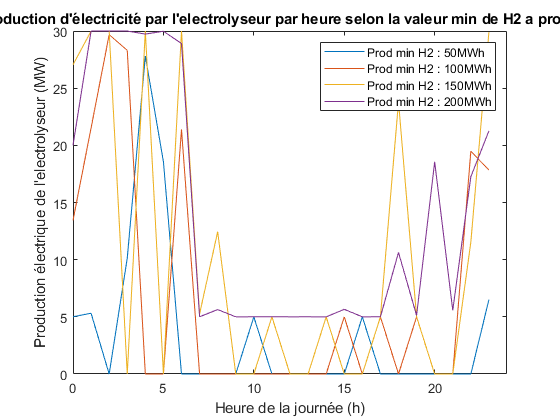

plot(H,mat_sol_ga(1:N,:))
title('Production d''électricité par l''electrolyseur par heure selon la valeur min de H2 a produire ')
xlabel('Heure de la journée (h)')
ylabel('Production électrique de l''electrolyseur (MW)')
legend('Prod min H2 : ' + string(Qjour_H2_ga) + 'MWh')
xlim([0 24])

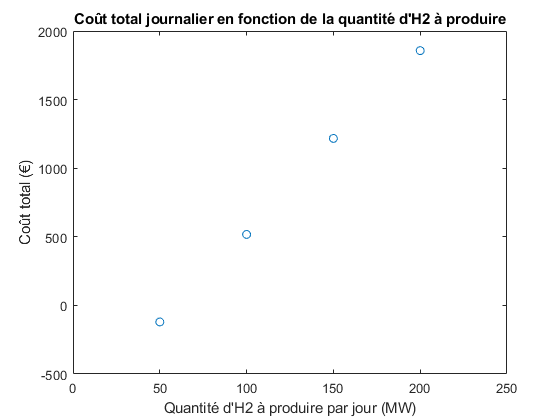

plot(Qjour_H2_ga, mat_fval_ga, 'O')
title("Coût total journalier en fonction de la quantité d'H2 à produire")
xlabel("Quantité d'H2 à produire par jour (MW)")
ylabel("Coût total (€)")
xlim([0 250])

**Conclusion sur l'étude paramétrique :** On remarque que plus la quantité minimale de H2 à produire par jour imposée augmente, plus le coût de fonctionnement de l'électrolyseur augmente. Cela peut paraître logique car on ne revend pas cet hydrogène pour le moment. 

### 6. Solver : particle swarm

% Ajout des contraines sous forme de pénalités
fobj_pso = @(X) fobj(X) + penalite(X, Qjour_H2_pso, etat_elec, N);
swarm_size = linspace(50,500,10);
s = length(swarm_size);

mat_sol_pso = zeros(2*N,s) ; 
mat_fval_pso = zeros(1,s) ; 

time_pso = zeros(1,s) ; 

for j = 1:s
    options_pso= optimoptions('particleswarm',"SwarmSize",swarm_size(j)) ; 
    tic
    [sol_pso,fval_pso,exitflag_pso,output_pso] = particleswarm(fobj_pso,2*N,lb,ub,options_pso) ;
    time_pso(1,j) = toc ; 
    mat_sol_pso(:,j) = sol_pso ; 
    mat_fval_pso(:,j) = fval_pso ; 
end

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxSta

### 7. Résultats avec le solver pso 

disp('Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque taille de population initiale (en MW)')

Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque taille de population initiale (en MW)


disp(mat_sol_pso(1:N,:))

         0   30.0000   10.1877   14.8121         0   30.0000   23.4166   30.0000   30.0000   30.0000
         0    0.2322    0.0015   24.0961   30.0000   30.0000   15.1146   30.0000   30.0000         0
    7.8972   30.0000   13.3946   30.0000    8.7432    1.0962   23.8647   28.4679   30.0000   30.0000
   30.0000   30.0000   28.7563   30.0000    3.4052   30.0000   10.5878   30.0000   30.0000   30.0000
   30.0000   30.0000   14.4439    1.2549   29.1172   30.0000   30.0000   30.0000   30.0000   29.9720
         0   30.0000   30.0000   30.0000         0         0   13.3501   29.4809   26.3180   30.0000
   30.0000   30.0000   30.0000   30.0000   29.6069   30.0000   30.0000    0.8986   29.3063   30.0000
    9.7465         0    0.1526    1.4811   30.0000    3.0653    3.0653         0   26.9190         0
   30.0000   12.4347         0   29.3703         0   30.0000         0    0.4105   27.2998         0
   28.1465   30.0000         0         0   13.8962         0   30.0000         0   28.6715 

disp('Les coûts journaliers optimaux pour chaque taille de population initiale (en €)')

Les coûts journaliers optimaux pour chaque taille de population initiale (en €)


disp(mat_fval_pso)

  543.2171  437.3387  576.3202  629.0042  659.6589  538.7664  570.8364  496.0327  392.4727  396.2431



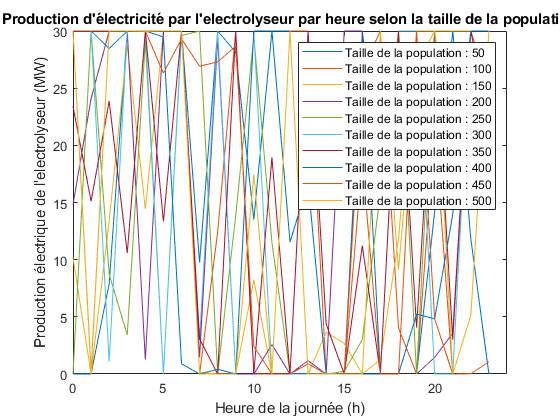

%Ce graphique est difficilement exploitable car nous avons testé trop de valeurs de taille de population
plot(H,mat_sol_pso(1:N,:))
title('Production d''électricité par l''electrolyseur par heure selon la taille de la population')
xlabel('Heure de la journée (h)')
ylabel('Production électrique de l''electrolyseur (MW)')
legend('Taille de la population : ' + string(swarm_size))
xlim([0 24])

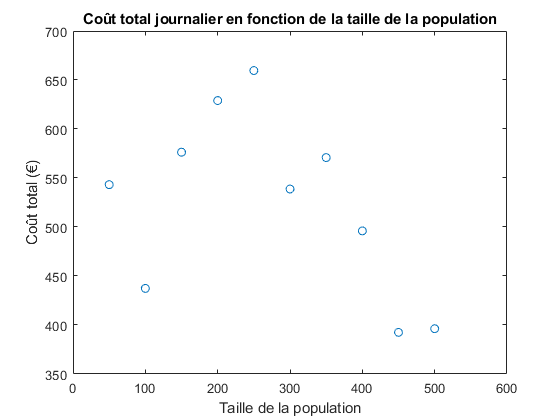

plot(swarm_size, mat_fval_pso, 'O')
title("Coût total journalier en fonction de la taille de la population")
xlabel("Taille de la population")
ylabel("Coût total (€)")
xlim([0 600])

**Conclusion : **On constate que la taille de la population n'influe pas vraiment sur la valeur du coût de fonctionnement. Cependant, on peut constater que sur la plage d'échantillons testés, le coût est minimal pour une population de taille 350. 

### 7. Analyse de la performance de la partie 1

disp('Nombre d''itérations avec ga')

Nombre d'itérations avec ga


disp(output_ga)

      problemtype: 'integerconstraints'
         rngstate: [1×1 struct]
      generations: 1059
        funccount: 212001
          message: 'Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance↵and constraint violation is less than options.ConstraintTolerance.'
    maxconstraint: 2.0046e-05
       hybridflag: []



disp('Nombre d''itérations avec solver pso')

Nombre d'itérations avec solver pso


disp(output_pso)

      rngstate: [1×1 struct]
    iterations: 82
     funccount: 41500
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'
    hybridflag: []



disp('Temps d''exécution de ga en secondes')

Temps d'exécution de ga en secondes


disp(mean(time_ga))

    9.2767



disp('Temps d''exécution de pso en secondes')

Temps d'exécution de pso en secondes


disp(mean(time_pso))

    1.2451



**Conclusion : **On constate que le solver ga fait beaucoup plus d'évaluations de la fonction que le solver PSO (funccont = 203 001 contre 20 000). 

Le temp moyen d'exécution du solver ga est également plus long que le temps moyen d'exécution du solver pso (9,27 secondes au lieu de 1,24 secondes. 

# **PARTIE 2 **

Cette fois-ci, on étudie la production d'électricité pendant une journée d'automne et on fait fonctionner la pile à combustible.

Nous souhaitons minimiser deux choses : 

**Objectif 1 : **utiliser le moins de dihydrogène sur 24h

**Objectif 2 : **minimiser le coût de la fourniture d’énergie sur 24h.

Dorénavant, la variable d'optimisation Y est un vecteur ligne 1x48. Les 24 premières colonnes correspondent aux puissances fournies à l'électrolyseur à chaque heure sur les 24h de la journée. Les 24 colonnes suivantes correspondent aux puissances produites par la PAC revendues sur le réseau. 

clear 

data2 = load ("AutonV50Nu40.txt") ;

%Répétition de certaines variables pour pouvoir exécuter la partie 2
%séparément de la partie 1
N = 24 ; 
Celec = ones(1,N) ; %Coût de fonctionnement de l'électrolyseur en €/MW
etat_elec = 0.6 ; %Rendement de l'électrolyseur 
Pmax_elec = 30 ;%Pmax de l'électrolyseur par heure en MW 
Pmin_elec = 5 ; %Pmin de l'électrolyseur par heure  en MW

%Données à chaque heure 
H2 = data2(:,1) ; %les 24 heures de la journée 
D2 = data2(:,2)'; %vecteur Nx1 des demandes en électricité par heure sur 24h en MW
Peol2 = data2(:,3)'; %vecteur de la puissance éolienne produite par heure en MW 
Ppv2 = data2(:,4)'; %vecteur de la puissance solaire produite par heure en MW
Cext2 = data2(:,end)' ; %Coût de l'électricité du réseau par heure en €/MW

%Autres données 
etat_pac = 0.8 ; 
Cpac = -4*ones(1,N) ; %coût de revente de l'électricité produite avec la PAC
QH2_max = 20 ; %en MWh
Pmax_pac = 15 ; %MW

### **1.Définition des fonctions objectif à minimiser** 

%1er terme : fonction objectif qui minimise la consommation de H2 
%2e terme : fonction objectif qui détermine le coût de fonctionnement de la centrale

fobj_part2 = @(Y) [sum( Y(1,N+1:end)/etat_pac + Y(1,1:N)*etat_elec ),(D2 +Y(1,1:N)-Y(1,N+1:end)- Peol2 - Ppv2)*Cext2' + Y(1,1:N)*Celec' + Y(1,N+1:end)*Cpac'] ; 

### **2.Définition des contraintes**

%Contraintes inégalités linéaires 

%Contrainte Σ𝜂𝑃𝐴𝐶 𝑃𝑃𝐴𝐶 ≤ 𝑄𝐻2𝑚𝑎𝑥 
Aineq_lin_part2 = [zeros(1,N),etat_pac*ones(1,N)] ;
bineq_lin_part2 = [QH2_max] ; 

%Contrainte égalité linéaire comprise dans la fonction objectif n°2
%Pext = D + Pelec - Peol - Ppv - Ppac (équation 1)

### 3. Définition des bornes

lb2 = zeros(1,2*N) ; 
ub2 = [Pmax_elec*ones(1,N) , Pmax_pac*ones(1,N)] ; 

### 4. Solver gamultiobj

%On déclenche le chronomètre 
 tic
 
[sol_gam,fval_gam,exitflag_gam,output_gam,population_gam,scores_gam] = gamultiobj(fobj_part2,2*N,Aineq_lin_part2,bineq_lin_part2,[],[],lb2,ub2) ;

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.



%On arrête le chrono 
time_gam = toc ; 

%Proposition de 10 profils de planification

disp('10 profils de planification avec gamultiobj')

10 profils de planification avec gamultiobj


disp(sol_gam(1:10,:))

  Columns 1 through 12

    0.0222    0.0002    0.0524    0.2723    0.0014    0.0002    0.0002    0.0006    0.7129    0.0000    0.0140    0.4579
    0.0260    0.0006    0.0536    0.2721    0.0014    0.0011    0.0002    0.0008    0.7005    0.0005    0.0140    0.3173
    0.0272    0.0040    0.0558    0.2704    0.0015    0.0005    0.0002    0.0018    0.7127    0.0010    0.0184    0.2111
    0.0352    0.0087    0.0565    0.2391    0.0021    0.0119    0.0027    0.0103    0.7119    0.0011    0.0193    0.1469
    0.0820    0.0128    0.0576    0.2781    0.0051    0.0172    0.0039    0.0258    0.7207    0.0014    0.0295    0.0789
    0.0355    0.0109    0.0577    0.1996    0.0021    0.0181    0.0039    0.0215    0.7202    0.0012    0.0194    0.0507
    0.0287    0.0093    0.0572    0.2541    0.0014    0.0122    0.0021    0.0020    0.6860    0.0021    0.0182    0.1552
    0.0274    0.0020    0.0550    0.2769    0.0026    0.0022    0.0007    0.0043    0.6898    0.0006    0.0144    0.2394
    0.02


disp('Valeurs des fonctions objectif associées')

Valeurs des fonctions objectif associées


disp(fval_gam(1:10,:))

   14.1374  714.5952
   14.2914  709.3903
   15.0365  695.3861
   26.1109  529.4680
   34.6768  408.8752
   35.1716  396.3929
   27.1618  513.6752
   14.7101  699.3142
   16.4641  674.4964
   34.0819  410.0773



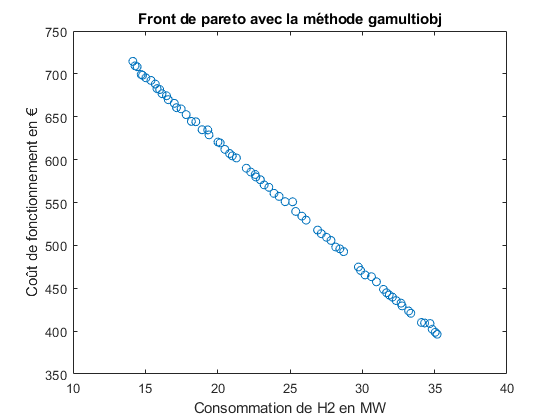


%tracé du front de pareto 
figure_gam = figure() ; 
plot(fval_gam(:,1),fval_gam(:,2),'o') ; 
title('Front de pareto avec la méthode gamultiobj') ;
xlabel('Consommation de H2 en MW') ; 
ylabel('Coût de fonctionnement en €') ; 

### 5. Solver paretosearch 

%On déclenche le chronomètre 
 tic
 
%options_pareto = optimoptions('paretosearch','ParetoSetSize',10); 
%Ce réglage d'option permet de ne calculer que 10 profils de planification.
%On ne l'utilise cependant pas car 10 points ne suffisent pas pour avoir un
%beau front de pareto.

[sol_pareto,fval_pareto,exitflag_pareto,output_pareto] = paretosearch(fobj_part2,2*N,Aineq_lin_part2,bineq_lin_part2,[],[],lb2,ub2) ; 


Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the spread of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.




%On arrête le chrono 
time_pareto = toc ; 

%Proposition de 10 profils de plannification 
disp('10 profils de planification avec paretosearch')

10 profils de planification avec paretosearch


disp(sol_pareto(1:10,:))

  Columns 1 through 12

    0.2041    6.5148         0    3.2335   13.5460         0    2.2960         0   16.8273         0         0         0
    0.2041    6.5148         0    3.2335   13.5460         0    2.2960         0   16.8273         0         0         0
    0.2041    6.5148         0    3.2335   13.5460         0    2.2960         0   16.8273         0         0         0
    0.2041    6.5148         0    3.2335   13.5460         0    2.2960         0   16.8273         0         0         0
    0.2041    6.5148         0    3.2335   13.5460         0    2.2960         0   16.8273         0         0         0
    0.2041    6.5148         0    3.2335   13.5460         0    2.2960         0   16.8273         0         0         0
    0.2041    6.5148         0    3.2335   13.5460         0    2.2960         0   16.8273         0         0         0
    0.2041    6.5148         0    3.2335   13.5460         0    2.2960         0   16.8273         0         0         0
    0.20

disp('Valeurs des fonctions objectif associées')

Valeurs des fonctions objectif associées


disp(fval_pareto(1:10,:))

   1.0e+03 *

    0.0667    1.3327
    0.0750    1.2255
    0.0699    1.2926
    0.0749    1.2317
    0.0685    1.3103
    0.0669    1.3308
    0.0744    1.2348
    0.0671    1.3281
    0.0720    1.2631
    0.0733    1.2447



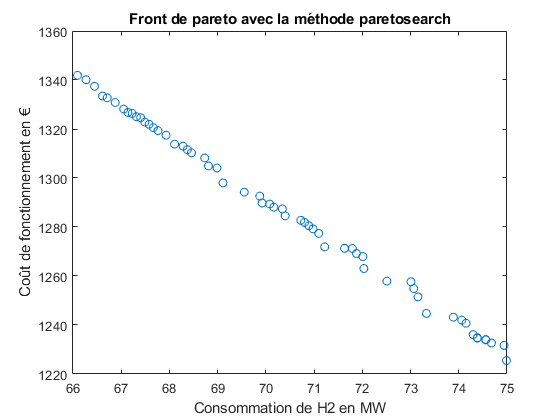

%tracé du front de pareto 
figure_pareto = figure() ; 
plot(fval_pareto(:,1),fval_pareto(:,2),'o') ; 
title('Front de pareto avec la méthode paretosearch') ;
xlabel('Consommation de H2 en MW') ; 
ylabel('Coût de fonctionnement en €') ; 

### 6. Comparaison des deux méthodes 

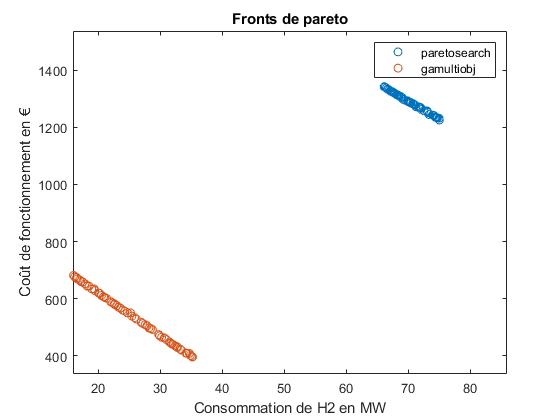

%tracé des 2 paretos 
figure_pareto = figure() ; 
plot(fval_pareto(:,1),fval_pareto(:,2),'o',fval_gam(:,1),fval_gam(:,2),'o') ; 
title('Fronts de pareto') ;
legend('paretosearch','gamultiobj') ; 
xlabel('Consommation de H2 en MW') ; 
ylabel('Coût de fonctionnement en €') ; 

xlim([15.9 85.9])
ylim([337 1537])

**Conclusion : **On remarque que la solution trouvée avec gamultiobj est plus optimisée que celle trouvée avec paretosearch : les valeurs de consommation en H2 et de coût sont plus faibles. 

### 7. Analyse de la performance de la partie 2 

disp('Nombre d''itérations avec gamultiobj')

Nombre d'itérations avec gamultiobj


disp(output_gam)

        problemtype: 'linearconstraints'
           rngstate: [1×1 struct]
        generations: 125
          funccount: 25000
            message: 'Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.'
      maxconstraint: 8.9227e-04
    averagedistance: 0.0051
             spread: 0.1234



disp('Nombre d''itérations avec paretosearch')

Nombre d'itérations avec paretosearch


disp(output_pareto)

         iterations: 17
          funccount: 18356
             volume: 631.7250
    averagedistance: 0.0024
             spread: 0.9987
      maxconstraint: 0
            message: 'Pareto set found that satisfies the constraints. ↵↵Optimization completed because the relative change in the spread of the Pareto set ↵is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within ↵'options.ConstraintTolerance'.'
           rngstate: [1×1 struct]



disp('Temps d''exécution de gamultiobj en secondes')

Temps d'exécution de gamultiobj en secondes


disp(time_gam)

   58.9532



disp('Temps d''exécution de paretosearch en secondes')

Temps d'exécution de paretosearch en secondes


disp(time_pareto)

    4.9591



**Conclusion :** On constate que le solver paretosearch fait moins d'évaluations de la fonction objectif que le solver gamultiobj (funccount = 18356 au lieu de 29800). Le temps d'exécution de paretosearch est donc beaucoup plus court (3,15 secondes au lieu de 44,18 secondes). Par contre, les solutions trouvées avec gamultiobj sont meilleures.

### Fonction pénalité du solver particle swarm 

Cette fonction permet de traduire les contraintes Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 ≥ 𝑄𝐻2𝑗𝑜𝑢r et teta est un entier. 

function [c] = penalite(X, Qjour_H2, etat, N)
%on choisit q=2 arbitrairement 
q=2 ; 

%Pénalité traduisant la contrainte Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 ≥ 𝑄𝐻2𝑗𝑜𝑢r
c = max(0, Qjour_H2 - etat*X(1:N)*X(N+1:2*N)')^q;

%Nous avons imposé dans les bornes du problème que : 0<teta<1. 
%Pour s'assurer que teta soit un entier, on impose qu'il vale soit 0 soit 1. 
%Pénalité si les teta ne valent pas 0 ou 1 : 
c2 = X(N+1:2*N)*(X(N+1:2*N)'-1); %c2 ne vaut 0 que si les teta valent O ou 1 

c = c + abs(c2)*1e10 ; 

%abs(c2) a une valeur entre 0 et 1. Plus il est proche de 1 (c'est à dire que les teta 
% ne valent pas 0 ou 1)
%plus la pénalité sera grande, et à l'inverse plus il est proche de 0 plus on se rapproche d'une 
% pénalité nulle 
%--> Si le solveur veut éviter la pénalité, il faut que les teta soient
%égaux à 0 ou 1

end